Companion software for "Volker Ziemann, *Hands-on Accelerator physics using MATLAB, CRCPress, 2019*" (https://www.crcpress.com/9781138589940)

# Triplet beam line with a small spot at the end (Section 3.7.2)

Volker Ziemann, 211119

In this example we first set the phase advance per cell in a triplet cell to be $90^o$ in both planes. In a second step, we then adjust the quadrupole excitations in such a way as to make a small beam spot at the end of the beam line.

We start by adding support for the 4D version of the software and define the geometry of the 12 m long triplet cell that we will base our design on. We use thin quadrupoles and make the focal lengths of the outer quads `Q1` and `Q3` twice as long and have the opposite polarity of the inner quadrupole `Q2`.

clear all
addpath ./4D   % support for the 4D support functions
global beamline sigma0  % make available to the chisq functions
triplet=[
  1,	10	0.5,	0;
  2,	1,	0,	  4;      % Q1
  1,	5,	0.2,	0;	
  2,	1,	0,	 -2;     % Q2
  1,	5,	0.2,	0;	
  2,	1,	0,  	4;     % Q3=Q1
  1,	10,	0.5,	0]

triplet =     1.0000   10.0000    0.5000         0
    2.0000    1.0000         0    4.0000
    1.0000    5.0000    0.2000         0
    2.0000    1.0000         0   -2.0000
    1.0000    5.0000    0.2000         0
    2.0000    1.0000         0    4.0000
    1.0000   10.0000    0.5000         0


beamline=triplet;

## Match the phase advance of a cell

In the first step we will match the phase advance in both planes to $90^o$ in both planes. We use fminsearch() to minimize the function chisq_tune_triplet(), defined in the appendix.

f0=[4,-2];      % starting guess
[f,fval]=fminsearch(@chisq_tune_triplet,f0)

f =     3.2191   -1.7390


fval = 2.6556e-11

triplet_matched=beamline;     % save for later

After updating the transfer matrices we determine the `periodic_beammatrix` with both emittances set to unity, such that `sigma0` contains the Twiss parameters.

[Racc,spos,nmat,nlines]=calcmat(beamline); 
Rturn=Racc(:,:,end);
sigma0=periodic_beammatrix(Rturn,1,1);  

Finally, we can use the function plot_betas() to dsiplay the beta functions. Additionally, we draw the magnet lattice on the same plot and give the plot a title.

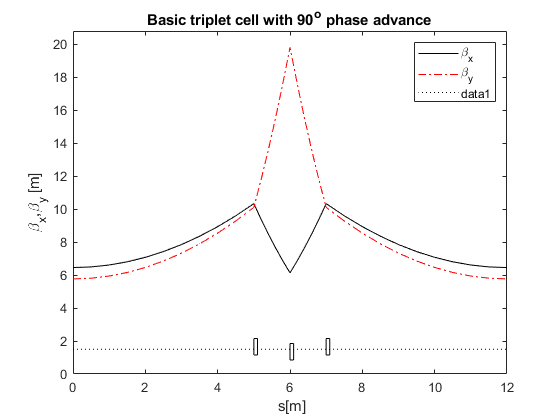

plot_betas(beamline,sigma0); 
drawmag(beamline,1,1);
title('Basic triplet cell with 90^o phase advance')

## Match a small spot at the end of a triplet beam line

Now we assemble a beam line with three triplet cells and add a little extra drift space with a variable negative length to the end. By changing this we can adjust the distance between the last quadrupole and the waist, where the beam size has the smallest spot size.  

nsteps=4

nsteps = 4

negdrift=[1,nsteps,-0.5,0];
beamline=[repmat(triplet_matched,3,1);negdrift]

beamline =     1.0000   10.0000    0.5000         0
    2.0000    1.0000         0    3.2191
    1.0000    5.0000    0.2000         0
    2.0000    1.0000         0   -1.7390
    1.0000    5.0000    0.2000         0
    2.0000    1.0000         0    3.2191
    1.0000   10.0000    0.5000         0
    1.0000   10.0000    0.5000         0
    2.0000    1.0000         0    3.2191
    1.0000    5.0000    0.2000         0


Having set the beamline  we now fit the quadrupole excitations such that the waist occurs at the end of the beamline and plot the beta functions along our beamline. The constraints to seek a the waist are $\beta_x=\beta_y=0.5\,$m and $\alpha_x=\alpha_y=0$.

f0=[4,-2,4,-2]; % starting guess
[f,fval]=fminsearch(@chisq_waist_triplet,f0)

f =     6.5838   -3.1530    2.2944   -1.3211


fval = 1.0503e-10

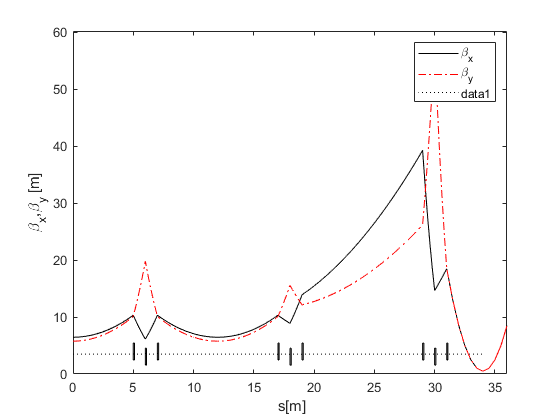

figure; plot_betas(beamline,sigma0); 
drawmag(beamline,2,3)

## Appendix

The function `chisq_tune_triplet()` receives two input parameters as` x`: the focal length of the outer quadrupoles and the focal length of the inner quadrupole of the triplet. Note that both outer quadrupoles are set to the same value. The function then returns the squared difference between the actual and the desired tune of the cell. The positions of the quadrupoles in the `beamline` is easily found from the definition of triplet at the beginning of this script.

function chisq=chisq_tune_triplet(x)
global beamline sigma0     % need info about the beamline
beamline(2,4)=x(1);   % outer quadrupole
beamline(4,4)=x(2);   % inner quadrupole
beamline(6,4)=x(1);   % outer quadrupole
[Racc,spos]=calcmat(beamline);
Rturn=Racc(:,:,end); 
[Qx,alpha0x,beta0x,gamma0x]=R2beta(Rturn(1:2,1:2));
[Qy,alpha0y,beta0y,gamma0y]=R2beta(Rturn(3:4,3:4));
chisq=(Qx-0.25)^2+(Qy-0.25)^2; % desired tunes, 0.25 -> 90 degrees
end

The function `chisq_waist_triplet()` receives four input parameters x: the focal lengths of the inner and outer quadrupoles of the last two triplet cells. The positions can be found from the `beamline` description. The function returns chisq, which is the squared difference between the actual and the desired values of the Twiss parameters, which are $\beta_x=\beta_y=0.5\,$m and $\alpha_x=\alpha_y=0$.

function chisq=chisq_waist_triplet(x)
global beamline sigma0      % need info about the beamline
beamline(9,4)=x(1); 
beamline(11,4)=x(2); 
beamline(13,4)=x(1);
beamline(16,4)=x(3); 
beamline(18,4)=x(4); 
beamline(20,4)=x(3);        
[Racc,spos]=calcmat(beamline); 
Rend=Racc(:,:,end); 
sigma=Rend*sigma0*Rend';
chisq=(sigma(1,1)-0.5)^2+(sigma(3,3)-0.5)^2+sigma(1,2)^2+sigma(3,4)^2;
end